# **InverseJacobiCD**

[Inverse of the Jacobi elliptic function cd](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{cd}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\sqrt{\frac{1-x^2 }{1-m\;x^2 }}\left|m\right.\right) & m\le 1\\
\frac{{\textrm{dc}}^{-1} \left(x\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{cd}}^{-1} \left(x,k\right)\equiv {\mathrm{cd}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  Jacobi form of the elliptic integral of the first kind.

Domain:  If $-\infty <m\le 1$ then $-1\le x\le 1$ . If $m>1$ then $1<|x|<\infty$.  For the specified domain, the  codomain  is the set of real numbers.

Basic features:

Special values:

${\mathrm{cd}}^{-1} \left(-1\left|m\right.\right)=2K\left(m\right)$,    ${\mathrm{cd}}^{-1} \left(0\left|m\right.\right)=K\left(m\right)$,    ${\mathrm{cd}}^{-1} \left(1\left|m\right.\right)=0$

${\mathrm{cd}}^{-1} \left(x\left|0\right.\right)=\cos^{-1} x$,    ${\textrm{cd}}^{-1} \left(x\left|1\right.\right)=\infty$

Identities:


$${\mathrm{cd}}^{-1} \left(\mathrm{cd}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{cd}\left({\textrm{cd}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x$$



$${\textrm{cd}}^{-1} \left(x\left|\frac{1}{2}\right.\right)=K\left(\frac{1}{2}\right)-F\left(\sin^{-1} \;x\left|\frac{1}{2}\right.\right)$$



$${\textrm{cd}}^{-1} \left(\frac{1}{2}\left|m\right.\right)=K\left(m\right)-F\left(\frac{\pi }{6}\left|m\right.\right)$$


$K\left(m\right)$ is the complete elliptic integral of the first kind and $F\left(x\left|m\right.\right)$ is  Legendre form of the elliptic integral of the first kind.

## Syntax

Y = InverseJacobiCD(X,K)

y = ijcd(x,k)

Y = mInverseJacobiCD(X,M)

y = mijcd(x,m)

## Description

**Y = InverseJacobiCD(X,K)** return${\;\mathrm{cd}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the scde size or any of them can be scalar. **InverseJacobiCD** is the wrapper function which calls the functions **ijcd** element-wise via the function **ufun2**.

**y = ijcd(x,k)** return the value of ${\mathrm{cd}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijcd** is the wrapper function which calls the functions **mijcd**.

**Y = mInverseJacobiCD(X,M)** returns ${\mathrm{cd}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parcdeter). X and M must be real and the scde size or any of them can be scalar. **mInverseJacobiCD** is the wrapper function which calls the functions **mijcd** element-wise via the function **ufun2**.

**y = mijcd(x,m)** compute value of ${\mathrm{cd}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parcdeter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijcd **call the function **melF **for calculation of ${\mathrm{cd}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
[ijcd(x,k), InverseJacobiCD(x,k), mijcd(x,k^2), mInverseJacobiCD(x,k^2)]

ans =    1.156321727760690   1.156321727760690   1.156321727760690   1.156321727760690


% Maple 1.156321727760690_22


Accuracy.

fprintf('%.16g\n',mijcd(0.5,-4)) 

0.5499964467091225


%  Maple  0.5499964467091224_31

Special values

m = -3; % m<1
disp(mijcd(-1,m)-2*melK(m))

     0



disp(mijcd(0,m) - melK(m))  % m < 1 !!!

     0



mijcd(1,m)

ans = 0

x=0.5;
disp(mijcd(x,0) - acos(x)) 

     0




disp(mijcd(x,1))

   Inf



Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mJacobiCD(mInverseJacobiCD(x,m),m)-x)

    -1.665334536937735e-16




k = 0.99995;
x = 0.9999*elK(k);
disp(InverseJacobiCD(JacobiCD(x,k),k)-x)

    -5.417888360170764e-13



m = 0.5;
disp(mijcd(1/2,m) - melK(m) + mpelF(pi/6,m))

    -1.110223024625157e-16



m = 2;
x = 1.2; % |x| > 1
disp(mijcd(x,m) - mijdc(x,1/m)/sqrt(m))

     0



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
disp(mInverseJacobiCD(1/2,m) - mEllipticK(m) + mpEllipticF(pi/6,m))

   1.0e-11 *

  -0.000033306690739  -0.000011102230246  -0.000022204460493  -0.101418873299508



**Matrix input**

m = [0.1, 0.5, 0.89; -1, -97, 0.99995 ]';
disp(mInverseJacobiCD(1/2,m) - mEllipticK(m) + mpEllipticF(pi/6,m))

   1.0e-11 *

  -0.000033306690739  -0.000022204460493
  -0.000011102230246  -0.000002775557562
  -0.000022204460493  -0.101418873299508



## **Plot **

**Example 1**

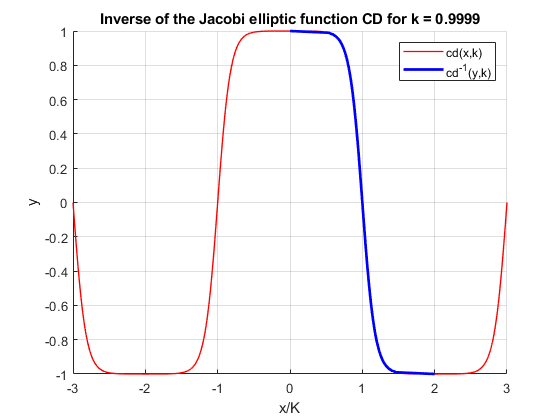

figure
hold on
x=-3:0.01:3;
k = 0.9999;
M = elK(k);
plot(x,JacobiCD(M*x,k),'LineWidth',1.0,'Color','red')
x=-1:0.01:1;
plot(InverseJacobiCD(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('cd(x,k)','cd^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Inverse of the Jacobi elliptic function CD for k = %g',k))
grid on
hold off

**Example 2**

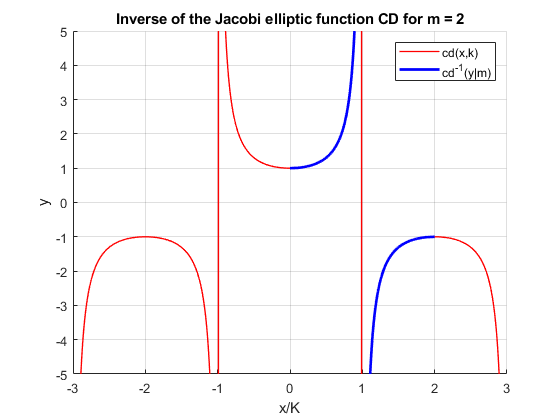

figure
hold on
x=-3:0.01:3;
m = 2;
if m < 1
    M = melK(m);
    xlabel('x/K')
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiCD(M*x,m),'LineWidth',1.0,'Color','red')
x=-12:0.01:12;
plot(mInverseJacobiCD(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('cd(x,k)','cd^{-1}(y|m)') %,'Position','best')

ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function CD for m = %g',m))
grid on
hold off

**Example 2**

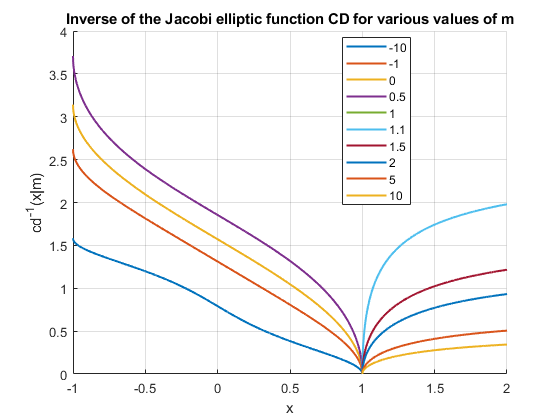

figure
hold on
X = -1:0.001:2;
M = [-10,-1,0,0.5,1,1.1,1.5,2,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiCD(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) 0 4])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function CD for various values of m')
%N=1:0.01:10;
%X = sqrt(1-1./N);
%plot(X,mInverseJacobiCD(X,N),'k-.')
xlabel('x')
ylabel('cd^{-1}(x|m)')

**Example 3**

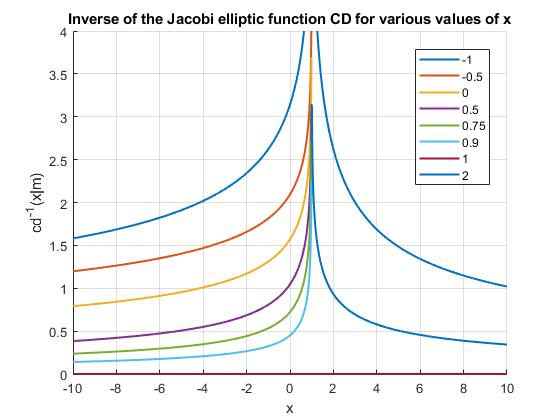

figure
hold on
M = -10:0.01:10;
X = [-1,-0.5,0,0.5,0.75,0.9,1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiCD(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
%axis([min(M) max(M) -3 3])
ylim([0  4])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function CD for various values of x')
xlabel('x')
ylabel('cd^{-1}(x|m)')
%M = 1:0.01:10;
%F = mInverseJacobiCD(sqrt(1-1./M),M);
%plot(M,F,'k-.')
%plot(M,-F)
hold off

**Example 4**

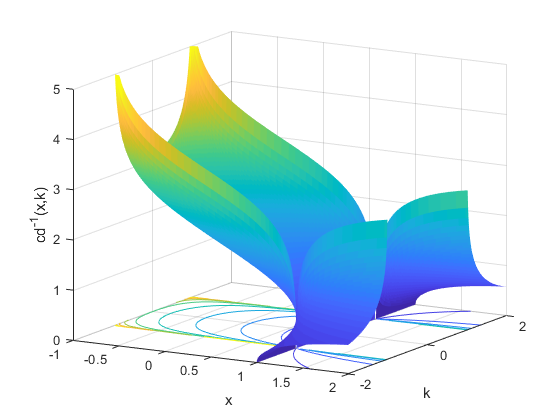

figure
x=-1:0.01:2;
k=-2:0.01:2;
zz = 5;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiCD(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view([30 15])
caxis([0 zz])
xlabel('x')
ylabel('k')
zlabel('cd^{-1}(x,k)')
zlim([0 zz])
grid on

**Example 4**

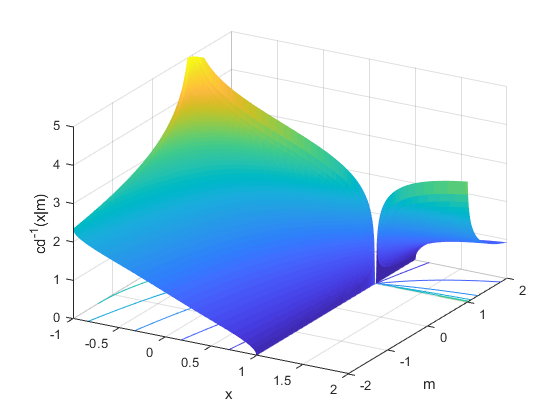

figure
x=-1:0.01:2;
m=-2:0.01:2;
zz = 5;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiCD(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view([30 30])
caxis([0 zz])
xlabel('x')
ylabel('m')
zlabel('cd^{-1}(x|m)')
zlim([0 zz])
grid on

**Example 5**

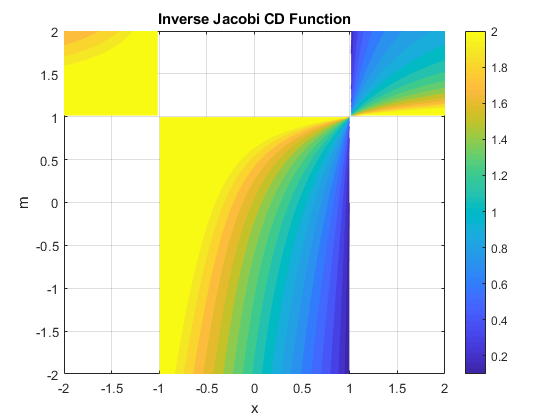

figure
f = @(x,m)mInverseJacobiCD(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi CD Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 6**

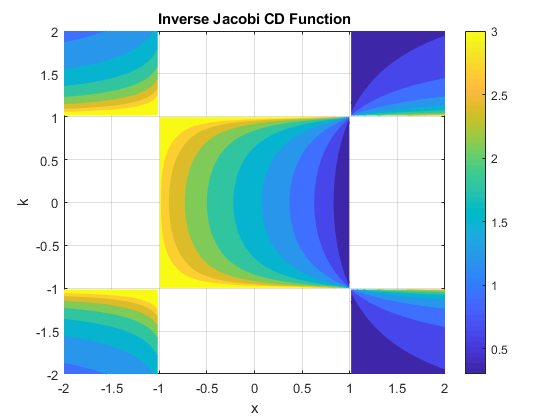

figure
f = @(x,k)InverseJacobiCD(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi CD Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also